## Testing ArmPos class

### Testing ArmPos.draw

plotting random positions for each point

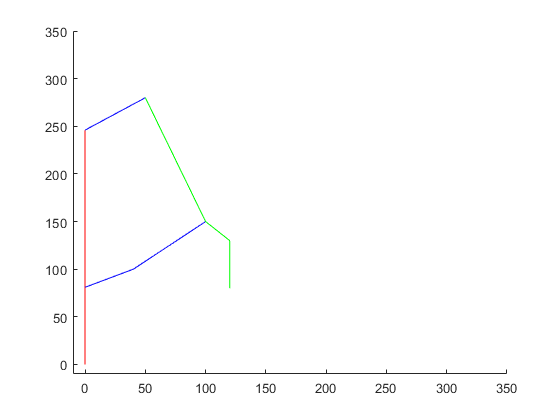

addpath("Kinematics")
pos = ArmPos();%initiate armposition object
pos.A = [50,280]; %setting position of the arm with random numbers
pos.B = [100,150];
pos.C = [120,130];
pos = pos.setD; %also testing setD
pos.E = [40,100];
pos.draw(); %drawing the a current configuration of the arm

### Testing ACtoB

what should be seen is that the arm from A to C is now straight

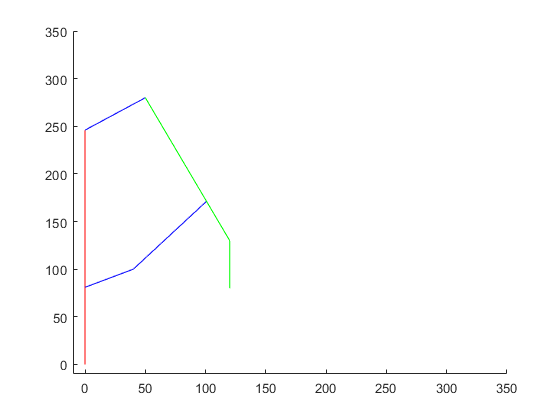

pos = pos.ACtoB();
pos.draw();

## Testing getAngle

pos.getAngle([0,0],[1,1]); % 45 degrees
pos.getAngle([0,0],[1,-1]); %-45 degrees
pos.getAngle([0,0],[-1,-1]); %-135 degrees
pos.getAngle([0,0],[-1,1]); %135 degrees

phi = 200;
phi_rad = 2*pi*phi/360

phi_rad = 3.4907

x = cos(phi_rad);
y = sin(phi_rad);
pos.getAngle([0,0],[x,y])

ans = -2.7925

pos.getAngle(pos.Z,pos.A) 

ans = 0.5972

pos = pos.getAngles

pos =   ArmPos with properties:

         L1: 81
         L2: 165
         L3: 80
         L4: 130
         L5: 130
         L6: 120
         L7: 65
         L8: 50
          X: [0 81]
          Z: [0 246]
    phiXmin: -10
    phiXmax: 140
    phiZmin: -45
    phiZmax: 80
          A: [50 280]
          B: [100.7463 171.2580]
          C: [120 130]
          D: [120 80]
          E: [40 100]
       phiX: 0.4434
       phiZ: 0.5972
       phi1: -0.4214


## Testing validation

pos.validate()

|EX| != L3
|BE| != L4
|AZ| != L5
|AB| != L6
|BC| != L7


ans = logical
   0


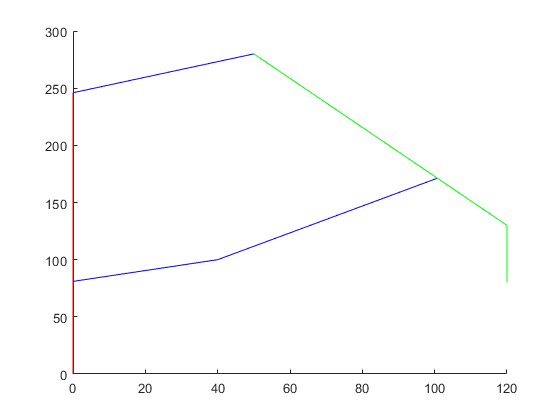

ans =   ArmPos with properties:

         L1: 81
         L2: 165
         L3: 80
         L4: 130
         L5: 130
         L6: 120
         L7: 65
         L8: 50
          X: [0 81]
          Z: [0 246]
    phiXmin: -10
    phiXmax: 140
    phiZmin: -45
    phiZmax: 80
          A: [50 280]
          B: [100.7463 171.2580]
          C: [120 130]
          D: [120 80]
          E: [40 100]
       phiX: 0
       phiZ: 0
       phi1: 0


pos.draw()

## Testing generating position from motor angles


x = ArmPos();
%input must be in radians

x.phiX = -0.069813;
x.phiZ = 0.64577;
%
x.phiX = 60/360 * 2 * pi;
x.phiZ = 30/360 * 2 * pi;
%}
tic
x = x.phiZXtoFullpos(true)

correct pos found


x =   ArmPos with properties:

         L1: 81
         L2: 165
         L3: 80
         L4: 130
         L5: 130
         L6: 120
         L7: 65
         L8: 50
          X: [0 81]
          Z: [0 246]
    phiXmin: 0.2000
    phiXmax: 1.4708
    phiZmin: -0.4000
    phiZmax: 0.3000
    phi1min: -0.7854
    phi1max: 0.7854
          A: [112.5833 311]
          B: [159.8284 200.6918]
          C: [185.4196 140.9415]
          D: [185.4196 90.9415]
          E: [40.0000 150.2820]
       phiX: 1.0472
       phiZ: 0.5236
       phi1: -0.6490


toc

Elapsed time is 0.011292 seconds.


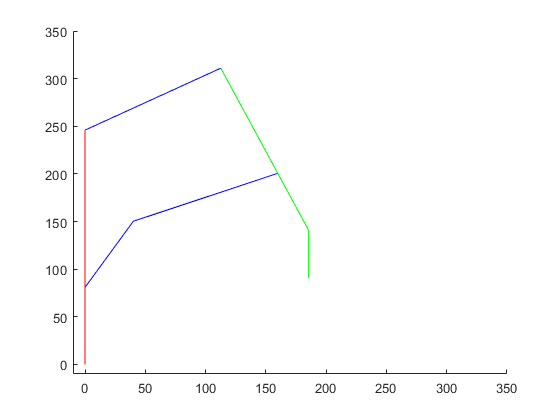

ans =   ArmPos with properties:

         L1: 81
         L2: 165
         L3: 80
         L4: 130
         L5: 130
         L6: 120
         L7: 65
         L8: 50
          X: [0 81]
          Z: [0 246]
    phiXmin: 0.2000
    phiXmax: 1.4708
    phiZmin: -0.4000
    phiZmax: 0.3000
    phi1min: -0.7854
    phi1max: 0.7854
          A: [112.5833 311]
          B: [159.8284 200.6918]
          C: [185.4196 140.9415]
          D: [185.4196 90.9415]
          E: [40.0000 150.2820]
       phiX: 1.0472
       phiZ: 0.5236
       phi1: -0.6490


x.draw()

### Testing the function on many possible angles

tic
for phiX=x.phiXmin:x.phiXmax
    phiX;
    for phiZ=x.phiZmin:x.phiZmax
        phiZ;
        x.phiZ = phiX/360 * 2 * pi;
        x.phiX = phiZ/360 * 2 * pi;
        x.phiZXtoFullpos(false); 
        x.validate(); %validating the position
    end
end

two correct pos found at-0.069813 and 0.64577
two correct pos found at0.05236 and 0.75049


toc

Elapsed time is 0.722584 seconds.
